
ts = out.ScopeData1{1}; 

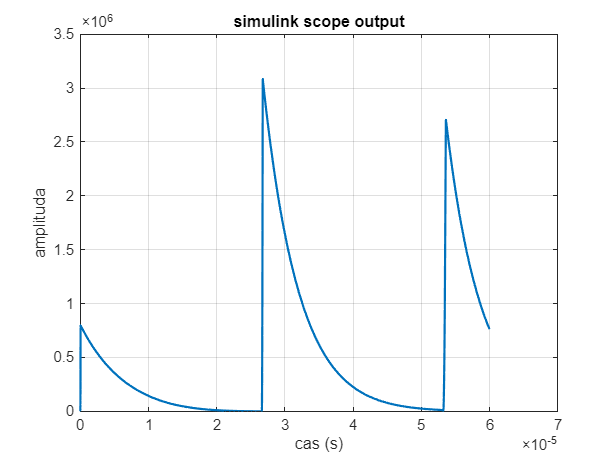

figure;
plot(ts.Values.Time, ts.Values.Data, 'LineWidth', 1.5);
xlabel('cas (s)');
ylabel('amplituda');
title('simulink scope output');
grid on;

time = ts.Values.Time; 
data = ts.Values.Data; 

indices = (time >= 0.000) & (time <= 2.5e-5);
integral_value = trapz(time(indices), data(indices))

integral_value = 4.5275

watt_hours = integral_value/3600

watt_hours = 0.0013